# ICEL9 Data Analysis Workshop

MATLAB version - J.I.M. Parmentier, collaboration with Christoffer Roepstorff

Utrecht University - August 2023

## Skeleton of the assignment - part 1 (Looking at 1 file)

- Declare the datapath and different needed information (e.g., horses identifiers, markers of interest) and load the file

- Extract information (labels (marker names), markers' trajectories, sampling rate, measurement duration), create a time vector, extract the trajectories of interest

- Visualise the data, see that some data have missing samples (Motion Capture)

- Deal with missing samples, if missing samples are less than 3 

- Extract the segment of interest (no missing data)

- Explore the effect of mean removal, fitlering 

- Stride split, based on LH hoof or LH fetlock (why LH? discuss it during the workshop)

- Extract the parameters of interest

- Save the parameters in a table (e.g., csv file)

## I. Load the data and declare the variables of interest

To load the data, you need to first define a datapath. You can copy-paste below where your data is located:

clear all; close all; clc;
datapath = 'C:\Users\ParmentierJIM\OneDrive - Universiteit Utrecht\ICEL9-DataAnalysis-Workshop\PonyKinematics\data';

In this section, we will work with the data of horse A at timepoint T0 only. You can define this in the following HorsesList variable:

HorsesList = {'horseA'};
TimePointsList = {'T0'};

We will work with three upper-body markers: Head ('Poll'), Withers ('T8') and the Pelvis ('TubSac'). You can define them below:

MarkersUpperBody = {'Poll','T8','TubSac'};
MarkersNames = {'Head','Withers','Pelvis'};

For splitting the data into strides for the analysis, we will use the left hind hoof ('Hoof_LH') and the left hind fetlock ('Fetl_LH') markers.

MarkersStrideSplit = {'Hoof_LH','Fetl_LH'};

You can now look for your data file and load it!

file = dir(strcat(datapath,'/',TimePointsList{1},'_',HorsesList{1},'_trot1.mat'));

if ~isempty(file)
    msgbox('Congratulations! You found a file. We are downloading it for you.');
    Data = load([file.folder,'/',file.name]);
else
    errordlg('We could not find a file. Please check your datapath, horse name and time point name.',...
        'File Error');
end

## II. Extract the trajectories

The datafile has a pre-defined organisation and contains more information than what we need today. We are going to extract the 3D displacements of 3 upper-body markers and 2 left hind limb markers.

First, we need to create variables with the needed information, as well as a time vector:

Trajectories = permute(Data.trot1.Trajectories.Labeled.Data,[3, 2, 1]); % 3D displacements data

MarkersName = Data.trot1.Trajectories.Labeled.Labels; % Markers names
Fs = Data.trot1.FrameRate; % Sampling frequency, in Hz
Time = 0:1/Fs:(Data.trot1.Frames-1)/Fs; % Creating a Time vector

In the MarkersName variable, we have a list of all available markers. In this list, we need to find the indices of the markers ones we want to use and that we have declared in lines 5 and 6.

ind_head = find(strcmp(MarkersName , MarkersUpperBody{1})==1); % Poll
ind_withers = find(strcmp(MarkersName , MarkersUpperBody{2})==1); % T8 (Withers)
ind_pelvis = find(strcmp(MarkersName , MarkersUpperBody{3})==1); % Tubera Sacrale (Pelvis)

ind_LHhoof = find(strcmp(MarkersName , MarkersStrideSplit{1})==1); % LH Hoof
ind_LHFetlock = find(strcmp(MarkersName , MarkersStrideSplit{2})==1); % LH Fetlock

Using the found indices of interest, we can extract the data for the different markers:

Head_data = Trajectories(:,:,ind_head); % Poll
Withers_data = Trajectories(:,:,ind_withers); % T8
Pelvis_data = Trajectories(:,:,ind_pelvis); % Tubera Sacrale
LHHoof_data = Trajectories(:,:,ind_LHhoof); % LH hoof
LHFetlock_data = Trajectories(:,:,ind_LHFetlock); % LH Fetlock

## III. Plot the trajectories of interest

We can now plot the displacements (x, y or z-axis) of the head, withers and pelvis. We can plot them one by one, on top of each other, or in individual suplots.

1. Plotting one-by-one:

axis = 3;
MarkerToPlot = 2;

figure
switch axis
    case 1
        str = 'X-axis';
    case 2
        str = 'Y-axis';
    case 3
        str = 'Z-axis';
end
switch MarkerToPlot
    case 1
        str_marker = 'Head';
        MTP = Head_data;
    case 2
        str_marker = 'Withers';
        MTP = Withers_data;
    case 3
        str_marker = 'Pelvis';
        MTP = Pelvis_data;
end

plot(Time,MTP(:, axis));
xlabel('Time (s)');
ylabel(strcat(str,' displacement (mm)'));
title(strcat(str,'-',str_marker));

2. Plotting all markers (1 axis) on the same graph:

figure
plot(Time,Head_data(:,axis)); hold on
plot(Time,Withers_data(:,axis));
plot(Time,Pelvis_data(:,axis));
xlabel('Time (s)');
ylabel(strcat(str,' displacement (mm)'));
title(strcat(str,' displacements of the Head, Withers and Pelvis markers'));
legend('Head','Withers','Pelvis');

3. Plotting all markers and all axes on consecutive subplots:

figure
ax(1) = subplot(311);
plot(Time,Head_data(:,1)); hold on
plot(Time,Head_data(:,2)); 
plot(Time,Head_data(:,3)); legend('x','y','z') 
title('Head');
xlabel('Time (s)'); 
ylabel('Displacement (mm)');
ax(2) = subplot(312);
plot(Time,Withers_data(:,1)); hold on
plot(Time,Withers_data(:,2));
plot(Time,Withers_data(:,3));
title('Withers');
xlabel('Time (s)');
ylabel('Displacement (mm)');
ax(3) = subplot(313);
plot(Time,Pelvis_data(:,1)); hold on;
plot(Time,Pelvis_data(:,2));
plot(Time,Pelvis_data(:,3));
title('Pelvis');
xlabel('Time (s)');
ylabel(strcat(str,' displacement (mm)'));

linkaxes(ax,'x');

In these curves, you might notice that the Head trajectories is missing some samples. This is due to the data collection process: Motion Capture. In Motion Capture, camera record the 3D position of markers. If a marker's position is occluded (e.g., the pony's hairs are covering the marker), the position is lost and the camera does not record data. If data are missed for a short time, we can interpolate the missing samples depending on the values of previous and following samples. We are going to explore this in the following section.

## IV. Deal with missing samples

For this assignment, we decided that we can deal with missing data for up to 5 consecutive samples. Above 5, we consider that it is too much missing data and that it is going to influence the results significantly.

MissingData = Head_data(:,3);

% Fill missing data
[cleanedData,missingIndices] = fillmissing(MissingData,"pchip","MaxGap",10,...
    "SamplePoints",Time);

% Display results
figure

% Plot cleaned data
plot(Time,cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(Time(missingIndices),cleanedData(missingIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices))

hold off
legend
xlabel("Time")
clear missingIndices

figure
plot(Time,MissingData,'LineWidth',2); hold on
plot(Time,cleanedData);
xlabel('Time (s)'); ylabel('Displacement (mm)')
legend('Missing samples data','Filled samples data')

## V. Extract a segment without missing data

You can see that because we have a gap bigger than 5 samples, we still have missing data. We are then going to work with a segment of this data that does not have issues.

Below, you can enter the beginning and end of this segment and then see how your extracted data looks like.

beginning_time = 5.22;
end_time = 11.59;

[~,beginning_ind] = min(abs(Time-beginning_time));
[~,end_ind] = min(abs(Time-end_time));

Extracted_Time = Time(beginning_ind:end_ind);
Extracted_Head_data = Head_data(beginning_ind:end_ind,:);
Extracted_Withers_data = Withers_data(beginning_ind:end_ind,:);
Extracted_Pelvis_data = Pelvis_data(beginning_ind:end_ind,:);
Extracted_LHHoof_data = LHHoof_data(beginning_ind:end_ind,:);
Extracted_LHFetlock_data = LHFetlock_data(beginning_ind:end_ind,:);

figure
ax(1) = subplot(311);
plot(Extracted_Time,Extracted_Head_data(:,3)); hold on
title('Head');
xlabel('Time (s)'); 
ylabel('Vertical displacement (mm)');
ax(2) = subplot(312);
plot(Extracted_Time,Extracted_Withers_data(:,3));
title('Withers');
xlabel('Time (s)');
ylabel('Vertical displacement (mm)');
ax(3) = subplot(313);
plot(Extracted_Time,Extracted_Pelvis_data(:,3));
title('Pelvis');
xlabel('Time (s)');
ylabel('Vertical displacement (mm)');

linkaxes(ax,'x');

figure
bx(1) = subplot(211);
plot(Extracted_Time,Extracted_LHHoof_data(:,3)); hold on
title('LH Hoof');
xlabel('Time (s)'); 
ylabel('Vertical displacement (mm)');
bx(2) = subplot(212);
plot(Extracted_Time,Extracted_LHFetlock_data(:,3));
title('LH Fetlock ');
xlabel('Time (s)');
ylabel('Vertical displacement (mm)');

linkaxes(bx,'x');

## VI. Prepare your data with mean removal, filtering, etc.

Now that you have extracted a segment of interest, we can prepare it for data analysis. Usually, we clean:

- movement artifacts (e.g., large head movements)

- Noise (e.g., noise related to the data collection process)

- Others

Today, we are going to look at the effect of different filters on the data.

toFilter_head = Extracted_Head_data(:,3)-mean(Extracted_Head_data(:,3));
toFilter_head = detrend(toFilter_head);

L = length(toFilter_head);
Y = fft(toFilter_head-mean(toFilter_head));
amp = 2*abs(Y)/L;
ang = angle(Y);
f = Fs*linspace(0,1,L);
figure
subplot(211)
plot(Extracted_Head_data(:,3)-mean(Extracted_Head_data(:,3))); hold on;
plot(toFilter_head);
subplot(212)
plot(f,amp); xlim([0 Fs/2]);

cutoff_lowpass = 0.5;
cutoff_highpass = 7;

[b,a] = butter(4,[cutoff_lowpass/(Fs/2),cutoff_highpass/(Fs/2)],'bandpass');

filtered_data_head = filtfilt(b,a,toFilter_head);

figure
plot(Extracted_Time,toFilter_head); hold on
plot(Extracted_Time,filtered_data_head);
legend('Raw','filtered');
xlabel('Time (s)');
ylabel('Vertical displacement (mm)');
title(strcat('Raw and band-pass Filtered data (Fc =[',num2str(cutoff_lowpass),', ',num2str(cutoff_highpass),']Hz)'));

## VII. Look at stride-splitting

Since trot is a cyclical movement, we can use limb data to stride-split. Conventionally, the different research groups have agreed to base the stride splitting on the left hind limb.

If sensors or markers are available on the hoof, you can privilege this. Otherwise, you can use the metatarsus marker, or even the pelvis markers.

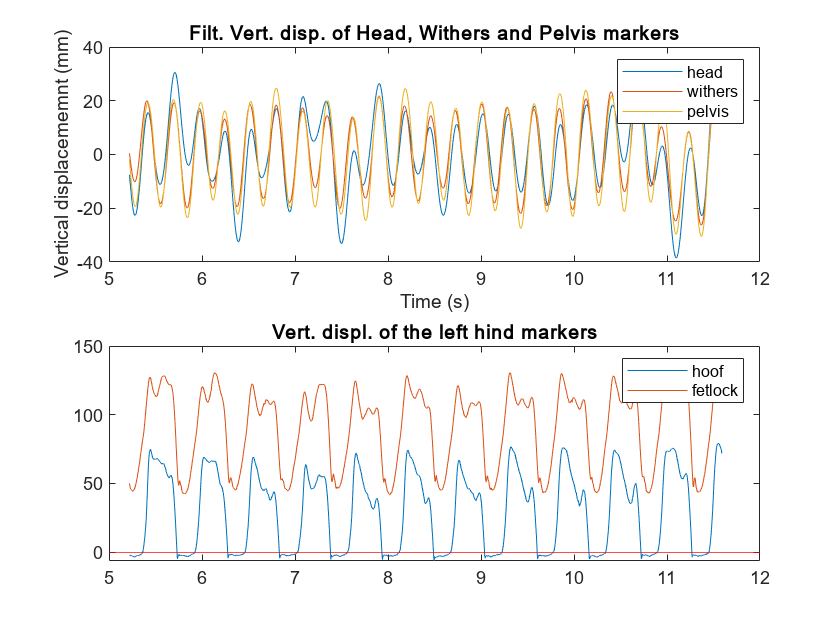

toFilter_withers = Extracted_Withers_data(:,3)-mean(Extracted_Withers_data(:,3));
toFilter_withers = detrend(toFilter_withers);
toFilter_pelvis = Extracted_Pelvis_data(:,3)-mean(Extracted_Pelvis_data(:,3));
toFilter_pelvis = detrend(toFilter_pelvis);

filtered_data_withers = filtfilt(b,a,toFilter_withers);
filtered_data_pelvis = filtfilt(b,a,toFilter_pelvis);

figure
subplot(211)
plot(Extracted_Time,filtered_data_head); hold on
plot(Extracted_Time,filtered_data_withers);
plot(Extracted_Time,filtered_data_pelvis); legend('head','withers','pelvis');
ylabel('Vertical displacememnt (mm)'); xlabel('Time (s)'); title('Filt. Vert. disp. of Head, Withers and Pelvis markers')
subplot(212)
plot(Extracted_Time,Extracted_LHHoof_data(:,3)); hold on
plot(Extracted_Time,Extracted_LHFetlock_data(:,3)); hold on
yline(0,'r','HandleVisibility','off');
title('Vert. displ. of the left hind markers');
legend('hoof','fetlock');

As you can see, the vertical foot marker is sometimes going below 0 which corresponds to the moments when the hoof is on the ground. We can use this to split the strides (i.e., when the LH lifts-off). We can detect these moments with a "zero-crossing" function.

LHHoof_z = Extracted_LHHoof_data(:,3);
LHFetlock_z = Extracted_LHFetlock_data(:,3);

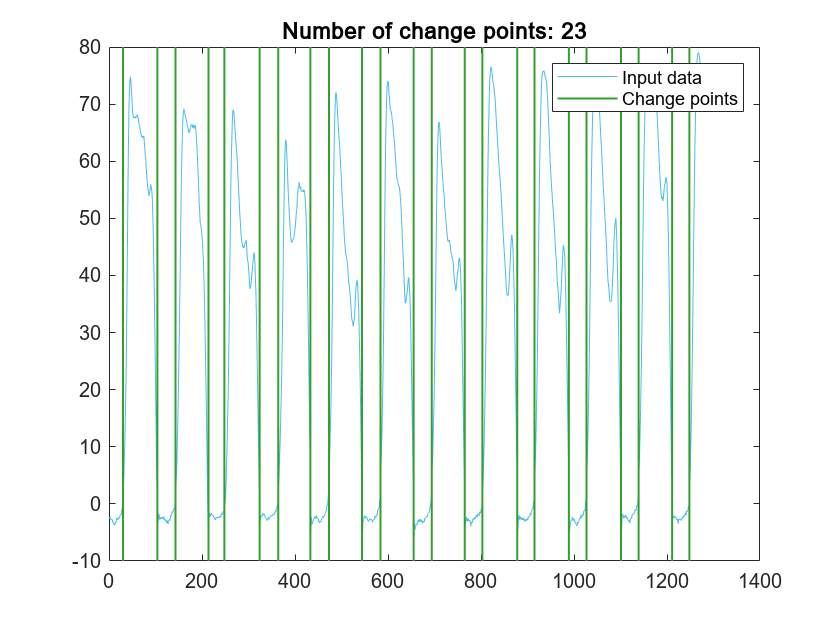

% Find change points
changeIndices_Hoof = ischange(LHHoof_z,"variance","Threshold",150);

% Display results
figure
plot(LHHoof_z,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot change points
x2 = repelem(find(changeIndices_Hoof),3);
y2 = repmat([ylim(gca) missing]',nnz(changeIndices_Hoof),1);
plot(x2,y2,"Color",[51 160 44]/255,"LineWidth",1,"DisplayName","Change points")
title("Number of change points: " + nnz(changeIndices_Hoof))

hold off
legend

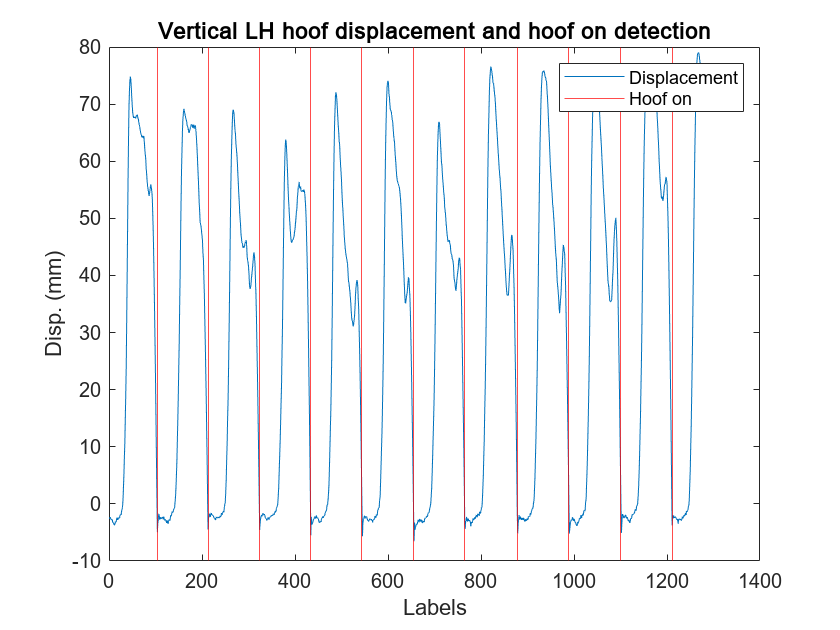

clear x2 y2
changeIndices_Hoof = find(changeIndices_Hoof==1);

for i = length(changeIndices_Hoof):-1:1
    if LHHoof_z(changeIndices_Hoof(i)+5) > 0
        changeIndices_Hoof(i) = [];
    end
end

figure
plot(LHHoof_z); hold on
xline(changeIndices_Hoof,'r'); 
title('Vertical LH hoof displacement and hoof on detection');
xlabel('Labels'); ylabel('Disp. (mm)');
legend('Displacement','Hoof on')

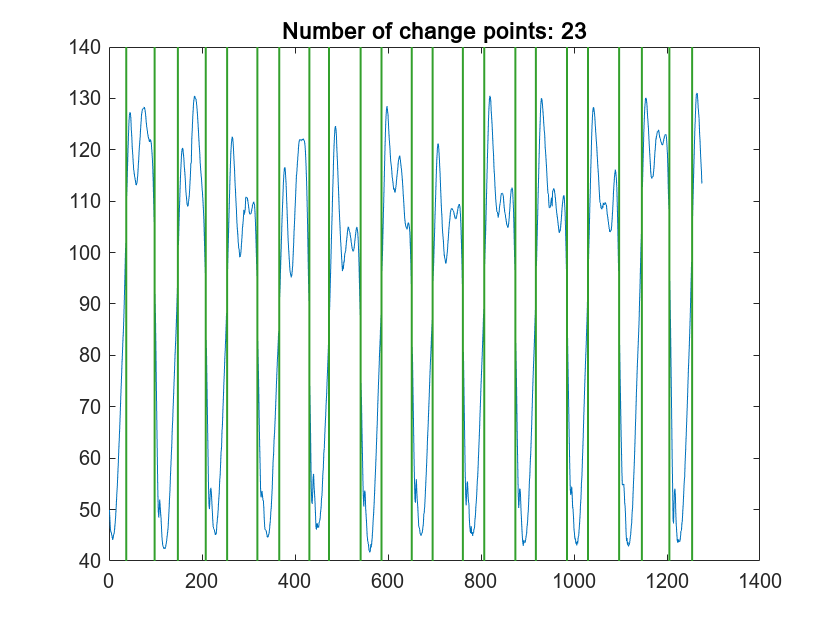

[changeIndices_Fetlock,~,~]= ischange(LHFetlock_z,"variance","Threshold",100);
figure
% plot(TF);
plot(LHFetlock_z);hold on; 
x = repelem(find(changeIndices_Fetlock),3);
y = repmat([ylim(gca) missing]',nnz(changeIndices_Fetlock),1);
plot(x,y,"Color",[51 160 44]/255,"LineWidth",1,"DisplayName","Change points")
title("Number of change points: " + nnz(changeIndices_Fetlock))

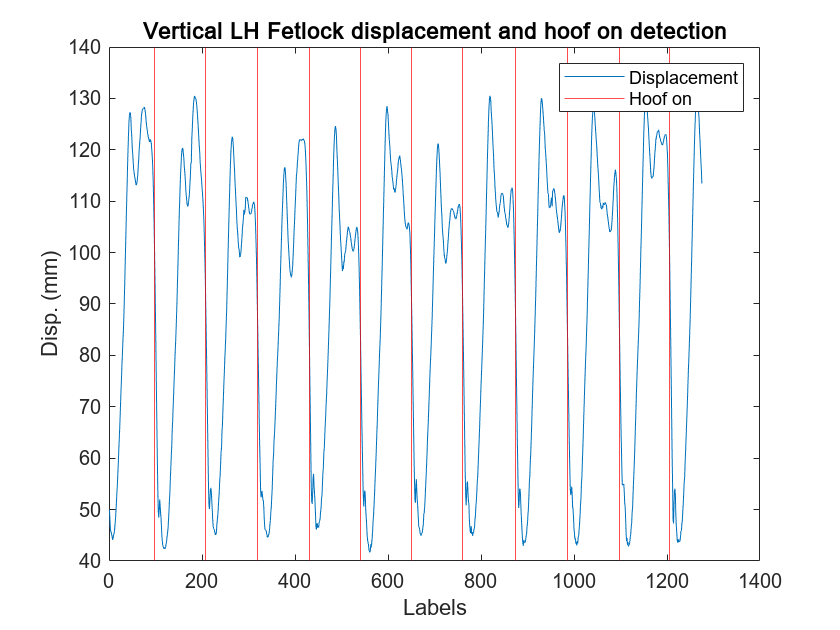

changeIndices_Fetlock = find(changeIndices_Fetlock==1);

for i = length(changeIndices_Fetlock):-1:1
    if LHHoof_z(changeIndices_Fetlock(i)+5) > LHHoof_z(changeIndices_Fetlock(i))
        changeIndices_Fetlock(i) = [];
    end
end

figure
plot(LHFetlock_z); hold on
xline(changeIndices_Fetlock,'r'); 
title('Vertical LH Fetlock displacement and hoof on detection');
xlabel('Labels'); ylabel('Disp. (mm)');
legend('Displacement','Hoof on')

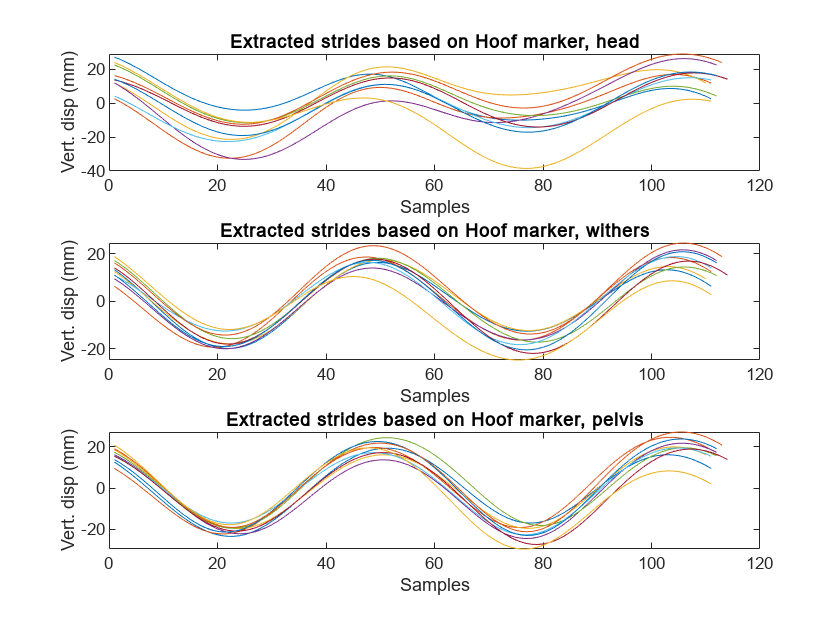

strides_Hoof = cell(length(changeIndices_Hoof)-1,3);
strides_Fetlock = cell(length(changeIndices_Fetlock)-1,3);

figure('Name','Hoof')
for i = 1:length(changeIndices_Hoof)-1
    strides_Hoof{i,1} = filtered_data_head(changeIndices_Hoof(i):changeIndices_Hoof(i+1));
    strides_Hoof{i,2} = filtered_data_withers(changeIndices_Hoof(i):changeIndices_Hoof(i+1));
    strides_Hoof{i,3} = filtered_data_pelvis(changeIndices_Hoof(i):changeIndices_Hoof(i+1));
    
    for k = 1:3
        subplot(3,1,k)
        plot(strides_Hoof{i,k}); hold on;
    end
end
subplot(311)
title('Extracted strides based on Hoof marker, head'); xlabel('Samples');ylabel('Vert. disp (mm)')
subplot(312)
title('Extracted strides based on Hoof marker, withers');xlabel('Samples');ylabel('Vert. disp (mm)')
subplot(313)
title('Extracted strides based on Hoof marker, pelvis');xlabel('Samples');ylabel('Vert. disp (mm)')

We add 10 samples to the stride to make sure to have the 2nd peak included in the stride.

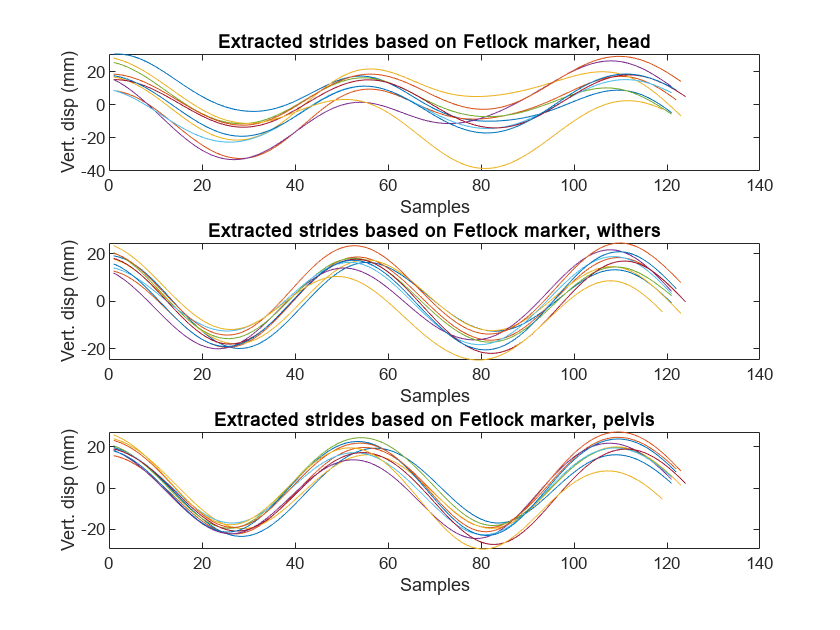

figure('Name','Fetlock')
for i = 1:length(changeIndices_Fetlock)-1
    strides_Fetlock{i,1} = filtered_data_head(changeIndices_Fetlock(i):changeIndices_Fetlock(i+1)+10);
    strides_Fetlock{i,2} = filtered_data_withers(changeIndices_Fetlock(i):changeIndices_Fetlock(i+1)+10);
    strides_Fetlock{i,3} = filtered_data_pelvis(changeIndices_Fetlock(i):changeIndices_Fetlock(i+1)+10);
    
    for k = 1:3
        subplot(3,1,k)
        plot(strides_Fetlock{i,k}); hold on;
    end
end
subplot(311)
title('Extracted strides based on Fetlock marker, head'); xlabel('Samples');ylabel('Vert. disp (mm)')
subplot(312)
title('Extracted strides based on Fetlock marker, withers');xlabel('Samples');ylabel('Vert. disp (mm)')
subplot(313)
title('Extracted strides based on Fetlock marker, pelvis');xlabel('Samples');ylabel('Vert. disp (mm)')

## VIII. Extract the variables of interest

We are mostly interested in: 

- Stride duration

- MaxDiff and MinDiff

MinDiff is the difference of minimum reached during the right stance minus the minimum reached during the left stance.

MaxDiff is the difference of maximum reached during the right stance minus the maximum reached during the left stance.

This means that if a MinDiff is positive, the minimum is during the left stance than during the right stance.

Since we cut strides based on LH-on, the first valley corresponds to the impact of LH-RF on the ground. Keep it in mind when defining which peak to substract to the other!

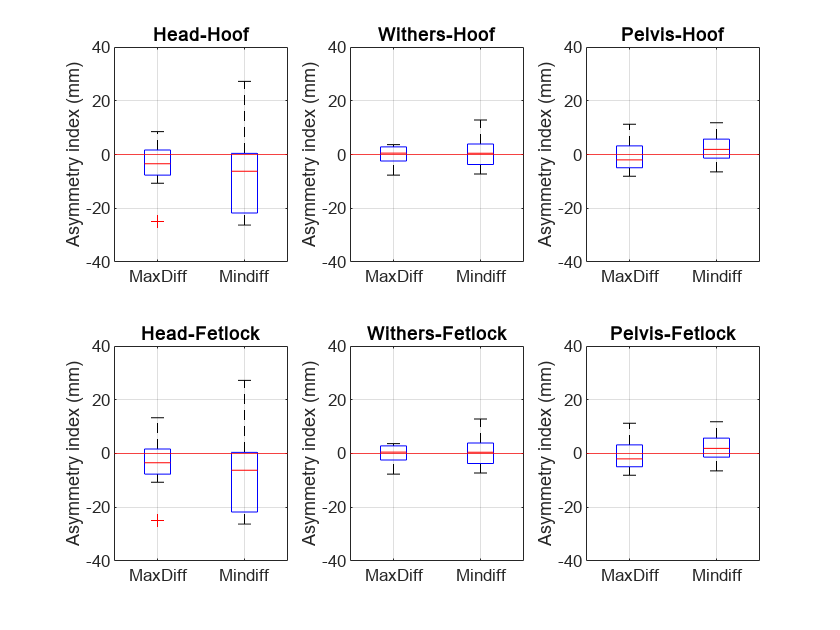

MaxDiff_Hoof = []; MinDiff_Hoof = []; StrideDuration_Hoof = [];
MaxDiff_Fetlock = []; MinDiff_Fetlock = []; StrideDuration_Fetlock = [];
for i = 1:size(strides_Hoof,1)
    for k =1:3
        [pks,~] = findpeaks(strides_Hoof{i,k});
        [~,ind] = findpeaks(-strides_Hoof{i,k});
        if k == 1 || 2 % k = 1 | 2 corresponds to Head or Withers
            MaxDiff_Hoof(i,k) = pks(1) - pks(2);           
            MinDiff_Hoof(i,k) = strides_Hoof{i,k}(ind(1)) - strides_Hoof{i,k}(ind(2));
        else % k = 3 corresponds to Pelvis
            MaxDiff_Hoof(i,k) = pks(2) - pks(1);           
            MinDiff_Hoof(i,k) = strides_Hoof{i,k}(ind(2)) - strides_Hoof{i,k}(ind(1));
        end
    end
    StrideDuration_Hoof(i) = Extracted_Time(changeIndices_Hoof(i+1))-Extracted_Time(changeIndices_Hoof(i));
end

for i = 1:size(strides_Fetlock,1)
    for k =1:3
        [pks,~] = findpeaks(strides_Fetlock{i,k});
        [~,ind] = findpeaks(-strides_Fetlock{i,k});
        if k == 1 || 2 % k = 1 | 2 corresponds to Head or Withers
            MaxDiff_Fetlock(i,k) = pks(1) - pks(2);           
            MinDiff_Fetlock(i,k) = strides_Fetlock{i,k}(ind(1)) - strides_Fetlock{i,k}(ind(2));
        else % k = 3 corresponds to Pelvis
            MaxDiff_Fetlock(i,k) = pks(2) - pks(1);           
            MinDiff_Fetlock(i,k) = strides_Fetlock{i,k}(ind(2)) - strides_Fetlock{i,k}(ind(1));
        end
    end
    StrideDuration_Fetlock(i) = Extracted_Time(changeIndices_Fetlock(i+1))-Extracted_Time(changeIndices_Fetlock(i));
end

figure
for k = 1:3
    subplot(2,3,k)
    tplot = [MaxDiff_Hoof(:,k),MinDiff_Hoof(:,k)];
    cgr = [repmat({'MaxDiff'},1,length(MaxDiff_Hoof(:,k))),...
        repmat({'Mindiff'},1,length(MinDiff_Hoof(:,k)))];
    boxplot(tplot,cgr);
    ylim([-40 40]); yline(0,'r');
    title(strcat(MarkersNames{k},'-Hoof')); ylabel('Asymmetry index (mm)'); grid on
end
for k = 1:3
    subplot(2,3,k+3)
    tplot = [MaxDiff_Fetlock(:,k),MinDiff_Fetlock(:,k)];
    cgr = [repmat({'MaxDiff'},1,length(MaxDiff_Fetlock(:,k))),...
        repmat({'Mindiff'},1,length(MinDiff_Fetlock(:,k)))];
    boxplot(tplot,cgr);
    ylim([-40 40]); yline(0,'r');
    title(strcat(MarkersNames{k},'-Fetlock')); ylabel('Asymmetry index (mm)'); grid on
end

## IX. Create a variable table and save it as .csv

Once you have worked on your data, you might want to save it and export it for statistical analysis.

temp_Hoof = [StrideDuration',MinDiff_Hoof(:,1),MaxDiff_Hoof(:,1),...
    MinDiff_Hoof(:,2),MaxDiff_Hoof(:,2),...
    MinDiff_Hoof(:,3),MaxDiff_Hoof(:,3)];
tempInfo = repmat([HorsesList(1),TimePointsList(1)],length(MinDiff_Hoof),1);
temptable1 = array2table(temp_Hoof);
temptable2 = cell2table(tempInfo);

results_Hoof = [temptable1,temptable2];
results_Hoof.Properties.VariableNames = {'StrideDuration',...
    'MinDiff_Head','MaxDiff_Head',...
    'MinDiff_Withers','MaxDiff_Withers',...
    'MinDiff_Pelvis','MaxDiff_Pelvis',...
    'HorseID','TimePoint'};

savepath = '.';
filename = strcat(savepath,'\HoofBasedResults-',HorsesList{1},'-',TimePointsList{1},'.csv');
writetable(results_Hoof,filename);

msgbox('Congratulations! You have finished the first part of this assignment.');

temp_Fetlock = [StrideDuration',MinDiff_Fetlock(:,1),MaxDiff_Fetlock(:,1),...
    MinDiff_Fetlock(:,2),MaxDiff_Fetlock(:,2),...
    MinDiff_Fetlock(:,3),MaxDiff_Fetlock(:,3)];
tempInfo = repmat([HorsesList(1),TimePointsList(1)],length(MinDiff_Fetlock),1);
temptable1 = array2table(temp_Fetlock);
temptable2 = cell2table(tempInfo);

results_Fetlock = [temptable1,temptable2];
results_Fetlock.Properties.VariableNames = {'StrideDuration',...
    'MinDiff_Head','MaxDiff_Head',...
    'MinDiff_Withers','MaxDiff_Withers',...
    'MinDiff_Pelvis','MaxDiff_Pelvis',...
    'HorseID','TimePoint'};

savepath = '.';
filename = strcat(savepath,'\HoofBasedResults-',HorsesList{1},'-',TimePointsList{1},'.csv');
writetable(results_Fetlock,filename);

msgbox('Congratulations! You have finished the first part of this assignment.');